# Home made Grid Search

close all
clear all
clc

## DATA 

We addressed the oversampling problem by using SMOTE on the training set alone, after splitting our data into train and test set using 80:20 ratio in Python (refer to the notebook in the coursework file).

training = readtable('train_balanced.csv', 'VariableNamingRule',"preserve");
training_unbalanced = readtable('train.csv', 'VariableNamingRule',"preserve");
testing = readtable('test.csv', 'VariableNamingRule',"preserve");

Partition our data into train, test and validation sets, and their corresponding predictive and response variables:

% train set
X_train = table2array(training_unbalanced(:, 1:end-1));
y_train = table2array(training_unbalanced(:, end));

rng('default') % For reproducibility
c = cvpartition(y_train,'KFold',5);
% test set
X_test = table2array(testing(:, 1:end-1));
y_test = table2array(testing(:, end));

load('GridSearch.mat');

## Grid Search - All Hyperparameters

tic
NumLearningCycle = 200;
MaxNumSplit = [10 20 30 50 70 100 125 150 200 250 300 350 400 450 500 550 600 650 700];
MinLeafSize = [1 2 3 4 5 7 10 15 20];

rng(9999,'twister');
savedRng = rng; % save the current RNG settings

GSmatrix=[];
indx = 0;
for i = 1:length(MaxNumSplit)
    for j = 1:length(MinLeafSize)
            indx=indx+1;
            rng(savedRng);
            GSt = templateTree('MaxNumSplits',MaxNumSplit(i),...
                'MinLeafSize', MinLeafSize(j),...
                'Reproducible',true);
            GSMdl = fitcensemble(X_train, y_train,...
                'CVPartition',c, ...
                'Method','Bag', ...
                'NumLearningCycles', NumLearningCycle, ...
                'Learners',GSt, ...
                'Prior',[26.5, 73.5], ...
                'Cost',[0 3; 1 0]);    

GSloss = kfoldLoss(GSMdl);


% Train results:
Predicted=kfoldPredict(GSMdl);
confMatGS=confusionmat(y_train,Predicted);  

% Total Accuracy = (TP+TN)/(TP+TN+FP+FN)
AccGS = (confMatGS(2,2)+confMatGS(1,1))/(sum(sum(confMatGS)));

% True Positive Rate, Sensitivity, Recall = TP/(TP+FN)
tprGS = confMatGS(2,2)/(confMatGS(2,2)+confMatGS(2,1));

% True Negative Rate, Specificity = TN/(TN+FP)
tnrGS = confMatGS(1,1)/(confMatGS(1,1)+confMatGS(1,2));

% Precision = TP/(TN+TP)
preGS = confMatGS(2,2)/(confMatGS(1,2)+confMatGS(2,2));

% f1 score
f1GS  = 2/(1/preGS + 1/tprGS);
% f2 score
f2GS = (5*preGS*tprGS)/(4*preGS+tprGS);

% Weighted Accuracy 73.5*TPR + 26.5*TNR
waccGS = (73.5*tprGS)+(26.5*tnrGS);

% G-Mean
gMeanGS = sqrt(tprGS * tnrGS);

[x,y,t,AUC,optROCpt] = perfcurve(y_train,Predicted,1);
[Xpr,Ypr,Tpr,AUCpr]=perfcurve(y_train,Predicted,1,  'xCrit', 'reca', 'yCrit', 'prec');

GSmatrix=[GSmatrix;MaxNumSplit(i),MinLeafSize(j),AccGS,...
    tprGS,tnrGS,preGS,f1GS, f2GS, AUC,AUCpr,GSloss, gMeanGS, waccGS];

    end
end
toc

Elapsed time is 2992.320376 seconds.


colNames = {'MaxNumSplit','MinLeafSize','Accuracy',...
    'Recall','Specificity','Precision', 'F1Score','F2score','AUC','AUCpr','KfoldLoss',...
    'GMean', 'WAcc'};
GStable14 = array2table(GSmatrix,'VariableNames',colNames)

GStable14 = 171×13 table
    MaxNumSplit    MinLeafSize    Accuracy    Recall     Specificity    Precision    F1Score    F2score      AUC       AUCpr      KfoldLoss     GMean      WAcc 
    ___________    ___________    ________    _______    ___________    _________    _______    _______    _______    ________    _________    _______    ______

        10              1         0.78275     0.83144      0.76516       0.56117     0.67008    0.75839     0.7983     0.06966     0.18613     0.79761    81.387
        10              2         0.78275     0.8

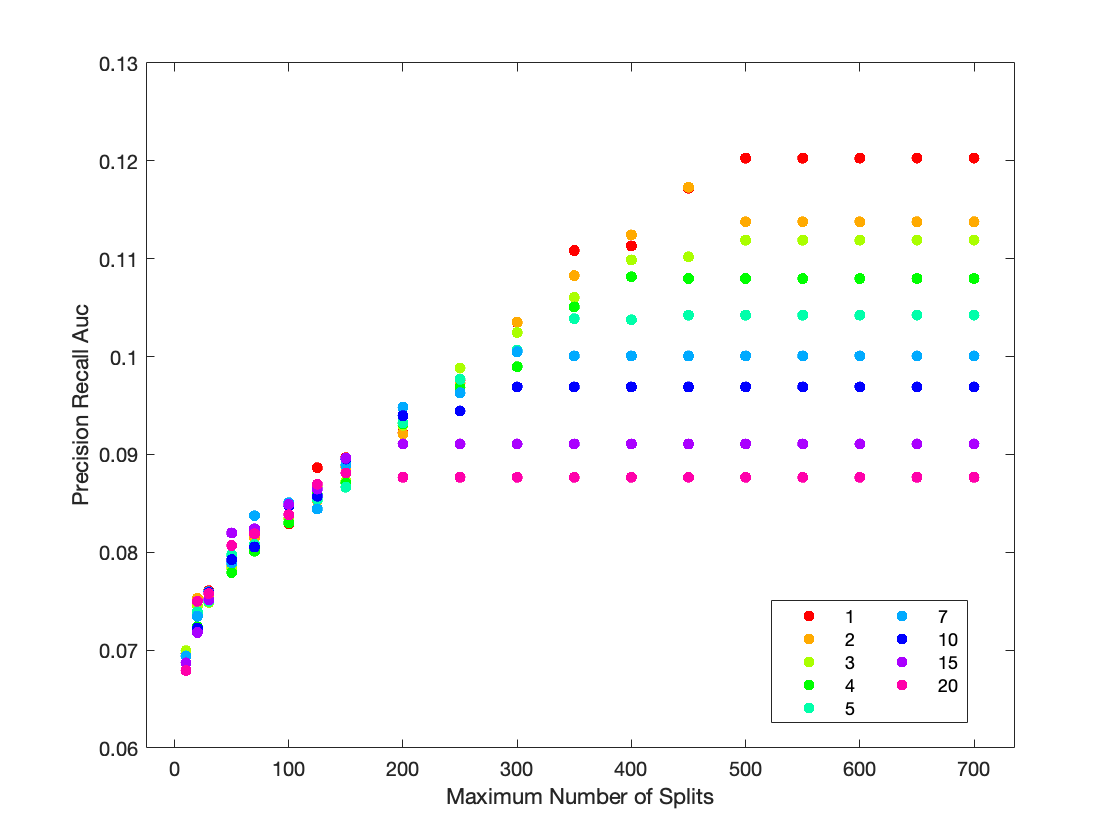

% Plot 
figure;
gscatter(GStable14.MaxNumSplit,(GStable14.AUCpr),GStable14.MinLeafSize)
ylabel('Precision Recall Auc');
xlabel('Maximum Number of Splits');
lgd = legend('Location','best');
lgd.NumColumns = 2;

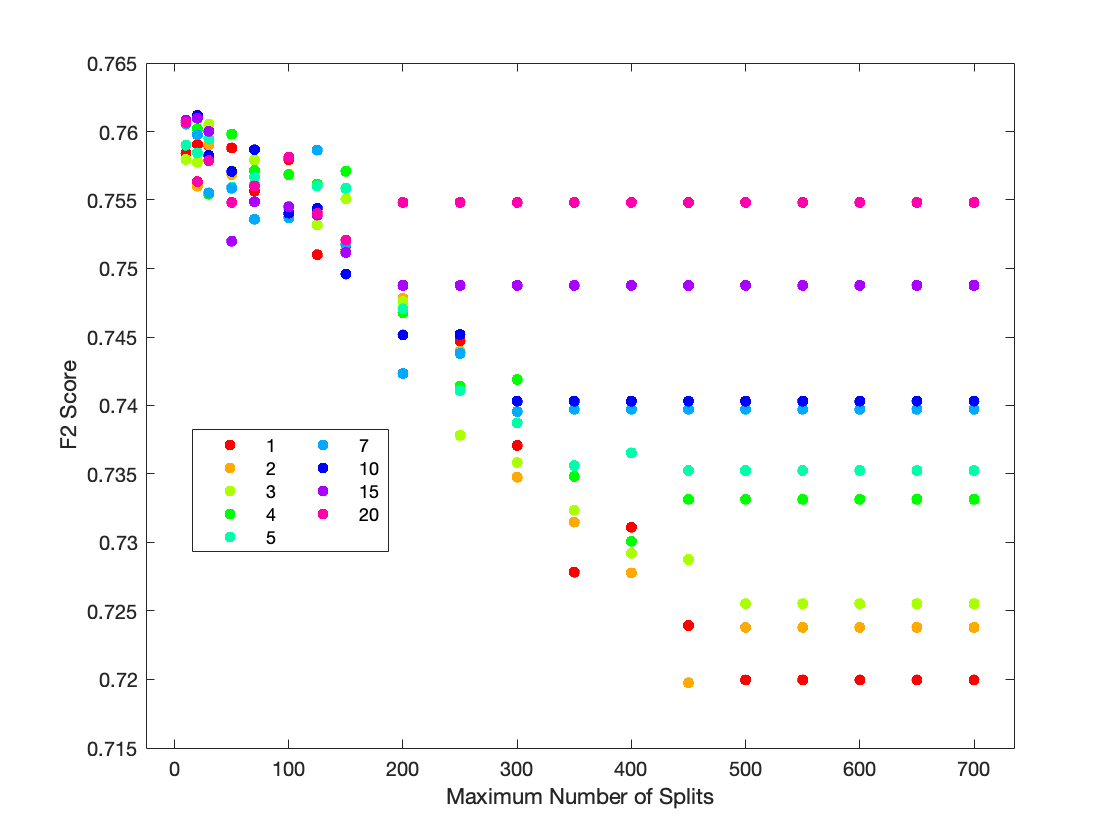

figure;
gscatter(GStable14.MaxNumSplit,(GStable14.F2score),GStable14.MinLeafSize)
ylabel('F2 Score');
xlabel('Maximum Number of Splits');
lgd = legend('Location','best');
lgd.NumColumns = 2;

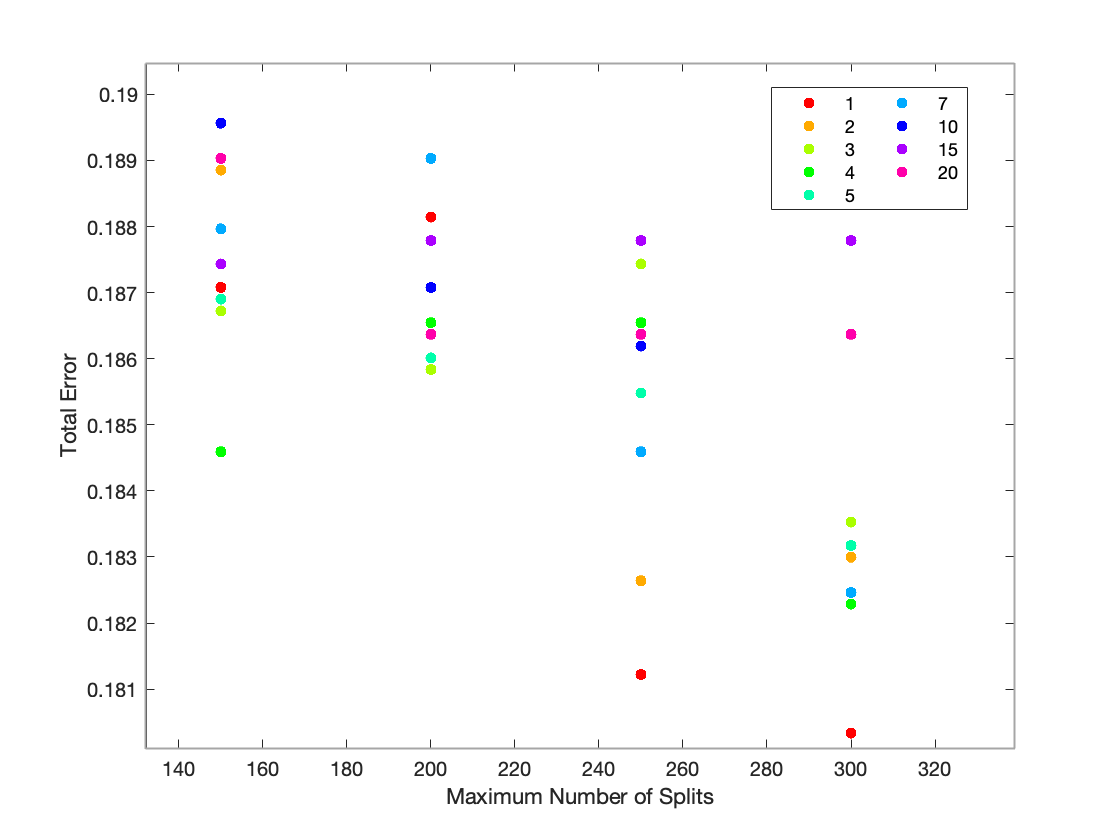

figure;
gscatter(GStable14.MinLeafSize,(1-GStable14.Accuracy),GStable14.MaxNumSplit)
ylabel('Total Error');
xlabel('Maximum Number of Splits');
lgd = legend('Location','best');
lgd.NumColumns = 2;

%Select the best F1 Score
Bestf14=GStable14(GStable14.AUCpr==max(GStable14.AUCpr),:)

Bestf14 = 5×13 table
    MaxNumSplit    MinLeafSize    Accuracy    Recall     Specificity    Precision    F1Score    F2score     AUC       AUCpr     KfoldLoss     GMean      WAcc 
    ___________    ___________    ________    _______    ___________    _________    _______    _______    ______    _______    _________    _______    ______

        500             1         0.82712     0.73846      0.85914       0.65442     0.6939     0.71997    0.7988    0.12028     0.22956     0.79652    77.044
        550             1         0.82712     0.73846      

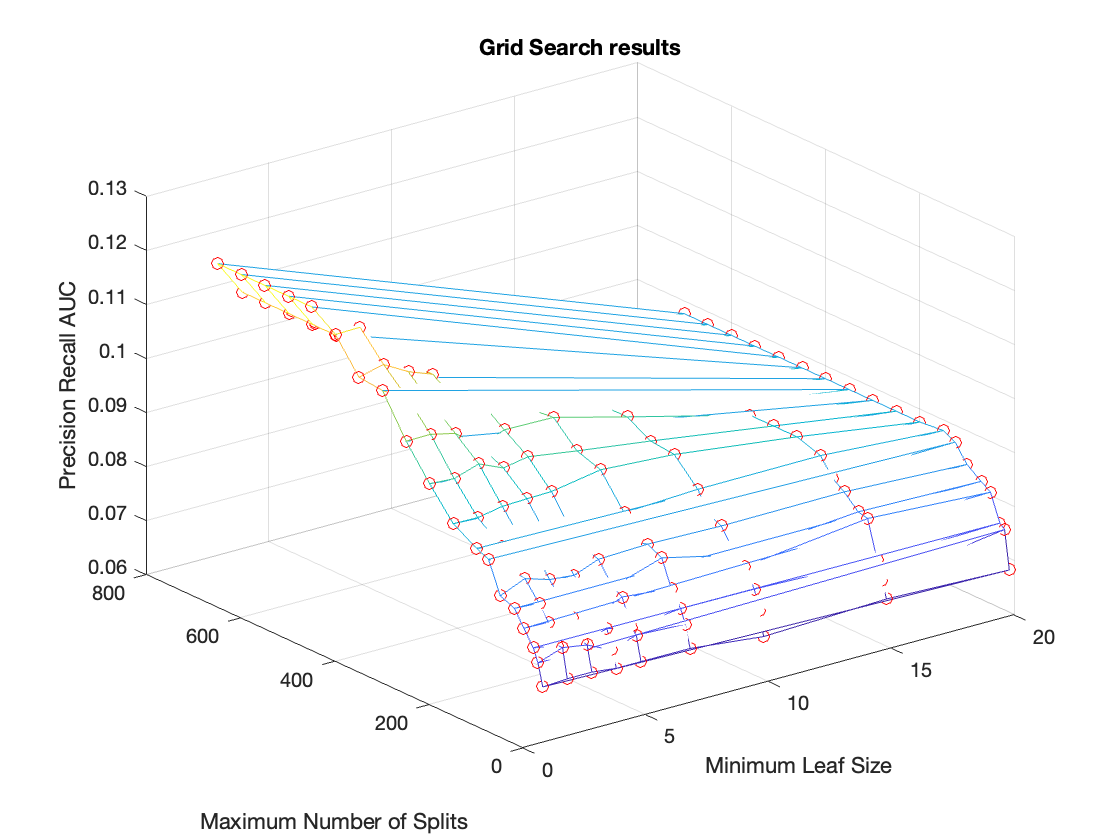

%Define a regular grid and interpolate the scattered data over the grid.
x=GStable14.MinLeafSize;
y=GStable14.MaxNumSplit;
z=(GStable14.AUCpr);

[mX,mY] = meshgrid(x,y);
mZ=griddata(x,y,z,mX,mY);

figure;
mesh(mX,mY,mZ);
shading flat
hold on;
plot3(x,y,z,'ro');
% xlim([-2.7 2.7])
% ylim([-2.7 2.7])
title('Grid Search results');
xlabel('Minimum Leaf Size');
ylabel('Maximum Number of Splits');
zlabel('Precision Recall AUC');
text(100,5,strcat('Accuracy gets bigger for higher MaxNumSplits'),'EdgeColor','k', 'Color','red','FontSize',14);
hold off;

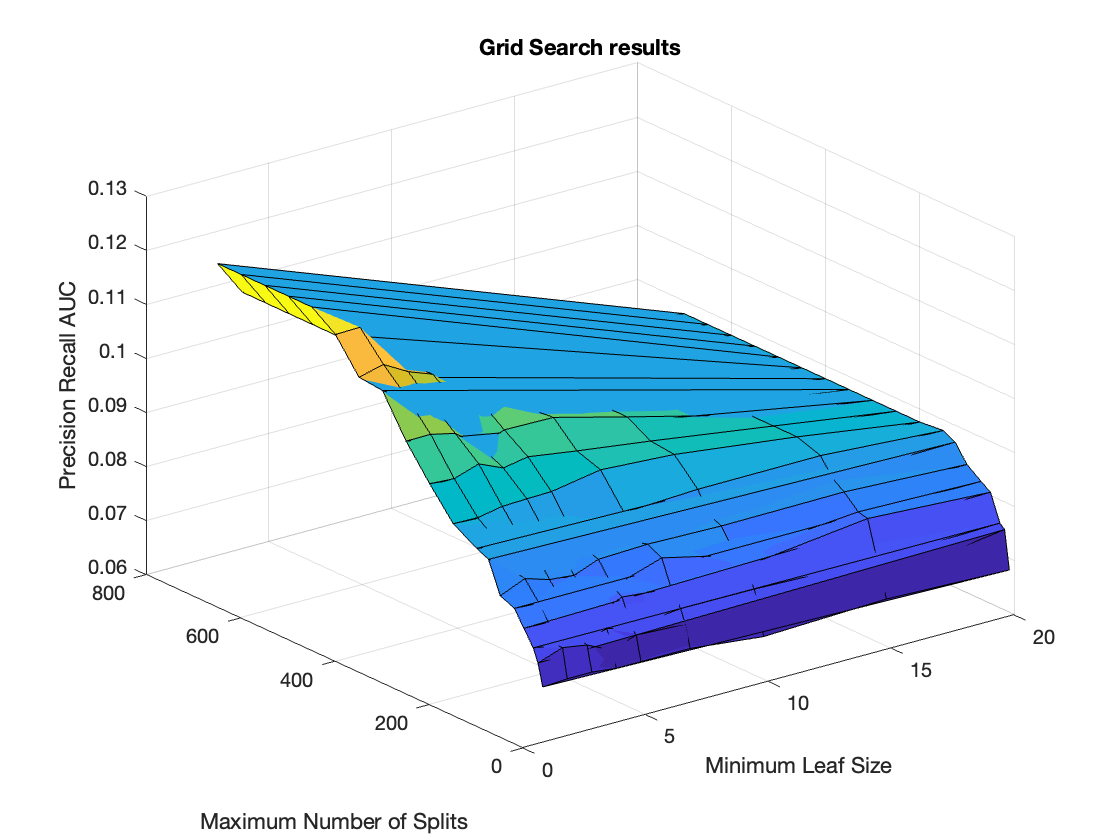

% 
figure;
surf(mX,mY,mZ);
title('Grid Search results');
xlabel('Minimum Leaf Size');
ylabel('Maximum Number of Splits');
zlabel('Precision Recall AUC');